%Code for the Difference Variance analysis 
%Here, the images intensity is normalized with the threshold DVA analysis

clear all,
clc
Ly = 235; Lx=235; TimeNum = 500; deltat=0.027;
%Symbols = 'osd^v<>ph+x';
DVAV = zeros(TimeNum-1, 22);
VarGlobal = zeros(1,22);

%input the image
addpath 'D:\Takeuchi_lab_UTokyo\Manuscript\Acitve_Glass\Codes\Orientation_Analysis'
input_image_list

for i=1:22
    Data = zeros(Ly,Lx,TimeNum);
    for t=1:TimeNum
        imArray = [Folder{i}, ImageName{i}, sprintf('%04d',t),'.tif'];
        Image = im2gray(imread(imArray));
        %Image = Image(111:324, 101:359);
        Image = imcrop(Image, [130.5, 11.5, 234, 234]);
        Image = double(Image)./ 255;
        ImageTh = adaptthresh(Image);
        Data(:,:,t) = Image./ImageTh - 1;
    end    
    for dt=1:(TimeNum-1)
        DVAV(dt,i) = mean((Data(:,:,1+dt:end) - Data(:,:,1:end-dt)).^2, 'all');
    end
    VarGlobal(i) = var(Data, 1, 'all');
end



PhiArray = [0.78    0.0121;
0.82    0.0158;
0.84    0.0099;
0.85    0.0163;
0.86    0.016;
0.87    0.0146;
0.88    0.0149;
0.91    0.0087;
nan nan;
0.92    0.0118;
nan nan;
0.9217  0.0112;
nan nan;
nan nan;
0.9382  0.01;
nan nan;
0.957   0.0078;
0.9583  0.0079];
ind = [1:8, 10,15,17];
PhiArrayStr = ["0.78", "0.82", "0.84", "0.85", "0.86", "0.87", "0.88", "0.91", "0.92", "0.94", "0.96"];

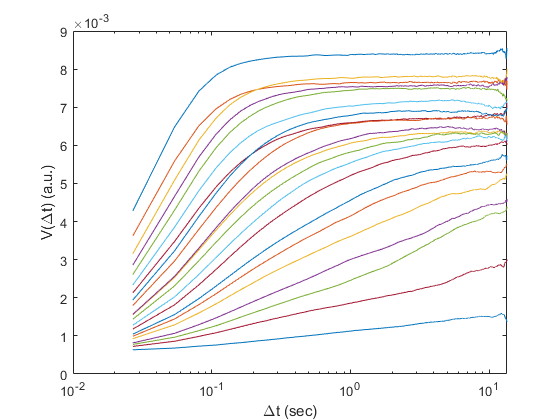

figure
%ind = [1:8, 9, 10,11, 12, 13, 14, 15, 16, 17];
ind = [1:22];
for i=1:22
    %semilogx([1:TimeNum-1]*deltat, DVAV(:,ind(i)), [Symbols(i),'-']);
    semilogx([1:TimeNum-1]*deltat, DVAV(:,ind(i)));
    hold on
end
xlabel('\Deltat (sec)'); ylabel('V(\Deltat) (a.u.)');

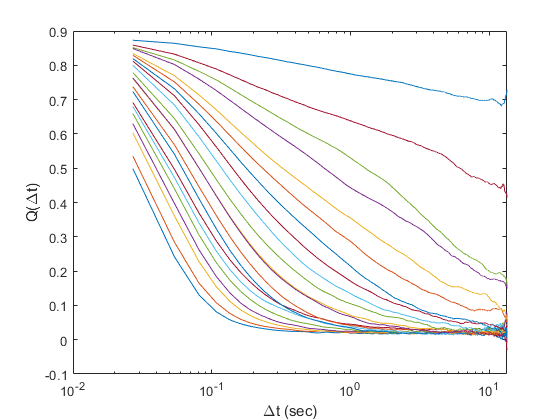

%legend(PhiArrayStr, 'Location','bestoutside')
figure
for i=1:22
    %semilogx([1:TimeNum-1]*deltat, 1-DVAV(:,ind(i))/(2*VarGlobal(ind(i))), [Symbols(i),'-']);
    semilogx([1:TimeNum-1]*deltat, 1-DVAV(:,ind(i))/(2*VarGlobal(ind(i))));
    hold on
end
xlabel('\Deltat (sec)'); ylabel('Q(\Deltat)');

%legend(PhiArrayStr, 'Location','bestoutside')

clf
ind = [1:8, 9, 10,11, 12, 13, 14, 15, 16, 17];
i = 16

i = 16

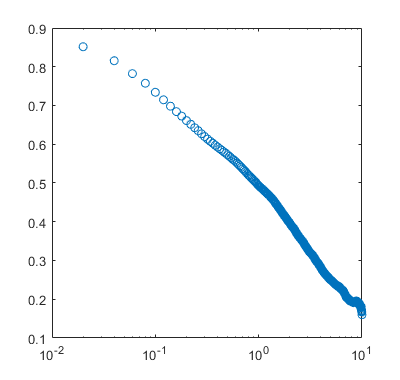

C = 1-DVAV(:,ind(i))/(2*VarGlobal(ind(i)));
t = [1:TimeNum-1]*deltat;
t1 = t(20:end);%reduced time
C1 = C(20:end)'; %reduced nematic orientation correlation function
%semilogx(t1, C1,'o')
semilogx(t, C, 'o')


xdata = t1;
ydata = C1;

fun = @(x,xdata) exp(-(xdata.*x(1)).^x(2)) + x(3);
x0 = [0.01 0.01 0.01]; %intitial value
lb = [-10 -10 -10]; %lower bound
ub = [1000 100 100]; %upper bound

%options = optimoptions('lsqcurvefit','Algorithm','levenberg-marquardt');
options = optimoptions('lsqcurvefit','Algorithm','trust-region-reflective');
%[obj,gof,opt] = lsqcurvefit(fun,x0,xdata,ydata, lb,ub, options)
%x = lsqcurvefit(fun,x0,xdata,ydata, lb,ub, options)

[x,resnorm,residual,exitflag,output,lambda,jacobian] = lsqcurvefit(fun,x0,xdata,ydata, lb,ub,options);


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


CI = nlparci(x, residual,'jacobian',jacobian); %confidence interval
X = [x' CI];
x1 = 1./X(1,:);
Table = [x1; X]

Table =     1.7502    1.8708    1.6441
    0.5714    0.5345    0.6082
    0.4077    0.4039    0.4114
    0.0405    0.0312    0.0498


range = [ydata(1) ydata(end)]

range =     0.5928    0.1602


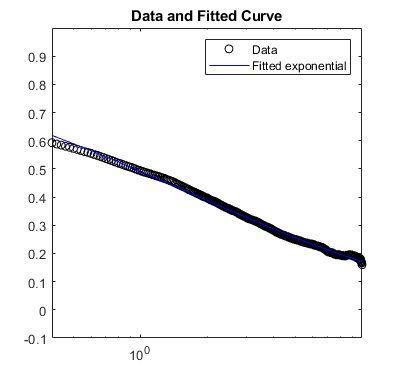

%X1 = [range' X(:,1) (X(:,2)-X(:,1)) ]

times = linspace(xdata(1),xdata(end));
semilogx(xdata,ydata,'ko',times,fun(x,times),'b-')
ylim([-0.1, 1.0])
legend('Data','Fitted exponential')
title('Data and Fitted Curve')

%Relaxation dynamics related to the translation degerees of freedom
clear all
clc
%packing fraction
phi = [0.783 0.795 0.819  0.838 0.851 0.857 0.875 0.879 0.908 0.9160 0.9217 0.9336 0.9355 0.9386 0.948];%
%phi = [ 0.78 0.80 0.84 0.85 0.86 0.87 0.88 0.91 0.92];
phi_err_neg = [0.012 0.02 0.02 0.01 0.016 0.016 0.0150 0.0149 0.009 0.012 0.01 0.01 0.01 0.01 0.01];
phi_err_pos = [0.012 0.02 0.02 0.01 0.016 0.016 0.0150 0.0149 0.009 0.012 0.01 0.01 0.01 0.01 0.01];

%Translation relaxation time 
tau = [0.0269  0.0292 0.0301 0.0375 0.0413 0.0468 0.0516 0.06311 0.0825 0.0951  0.135  0.2795  0.5017  1.3283 1.7502]; %in s
%tau = [0.03  0.04 0.05 0.05 0.06 0.07 0.08 0.12 0.16]; %in s
tau_err_neg = [0.001  0.001 0.001 0.001 0.002 0.003 0.004 0.003 0.006 0.007 0.007 0.007 0.007 0.007 0.007];
tau_err_pos = [0.001  0.001 0.001 0.001 0.002 0.003 0.004 0.003 0.006 0.007 0.007 0.007 0.007 0.007 0.007];

xdata = phi;
ydata = tau;
fun = @(x,xdata) x(1).*((x(2) - xdata).^x(3));
x0 = [0.008, 1, 0.1]; %intitial value
%x0 = [0.8, 1, 0.6]; %intitial value
%x0 = [0.9, 1, 0.8]; %intitial value
lb = [-5, -50, -5]; %lower bound
ub = [5, 50, 5]; %upper bound

options = optimoptions('lsqcurvefit','Algorithm','levenberg-marquardt');
%[obj,gof,opt] = lsqcurvefit(fun,x0,xdata,ydata, lb,ub, options)
[x,resnorm,residual,exitflag,output,lambda,jacobian] = lsqcurvefit(fun,x0,xdata,ydata, lb,ub,options);


Solver stopped prematurely.

lsqcurvefit stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 6.000000e+02.



CI = nlparci(x, residual,'jacobian',jacobian); %confidence interval 95%
X = [x' CI];
X1 = [X(:,1) abs(X(:,2)-X(:,1))]

X1 =     0.0001    0.0011
    0.9761    0.0968
   -2.8953    7.8007



clf
times = linspace(xdata(1),xdata(end));
Fit_dat1 = [times' fun(x,times)']; %Data with the fitted parameter


fig = figure

fig =   Figure (35) with properties:

      Number: 35
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


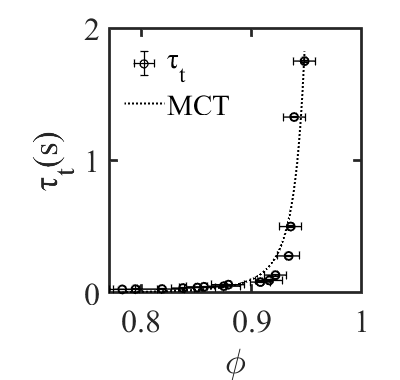

errorbar(phi, tau, tau_err_neg, tau_err_pos, phi_err_neg, phi_err_pos,"Marker",'o', "Color",'black', ...
    "MarkerEdgeColor","auto","LineStyle","none", "MarkerSize",6, "LineWidth",1.0)
hold on
plot(times, fun(x,times), ':', xdata, ydata, 'o', "Color","Black", "MarkerEdgeColor","auto", "LineWidth",1.5)
hold off

xlabel('\phi') 
ylabel('τ_t(s)')
%ylim([0.0, 0.2])
%xlim([0.75, 0.95])
set(gcf,'Position',[100 100 400 380])
set(gca, 'FontName', 'Times', 'FontSize', 24, 'FontWeight', 'normal', 'LineWidth', 2)%'XTick',[0.01 0.1 1 10])
set(gca,'TickLength',[0.03, 0.03])
legend("τ_t", "MCT","Location","northwest","Box","off")
print(fig,'Translation_relaxation','-dpng')

% w = 10;
% VarGlobal = var(Data, 1, 'all');
% VarLocal = zeros(Ly,Lx);
% for iy=1:Ly
%     for ix=1:Lx
%         indy = [max(1,iy-w):min(Ly,iy+w)]; 
%         indx = [max(1,ix-w):min(Lx,ix+w)];
%         VarLocal(iy,ix) = var(Data(indy,indx,:), 1, 'all');
%     end
% end
% hold off
% semilogx([1:499]*0.02, DVAV, 'o-')
% hold on
% plot(10.^[-2,1], repmat(VarGlobal*2, 1, 2), '-k')
% xlabel('\Deltat (sec)'); ylabel('V(\Deltat)');
% legend('Data', 'var x2', 'Location','southeast')